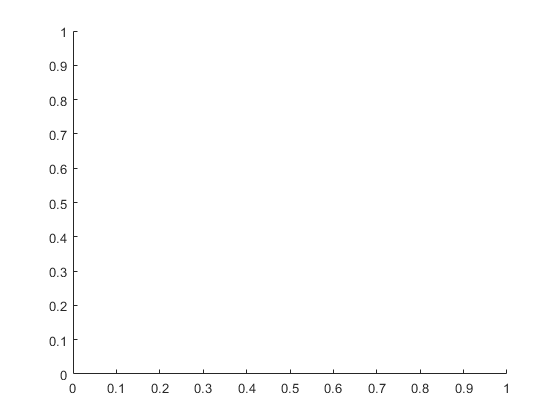

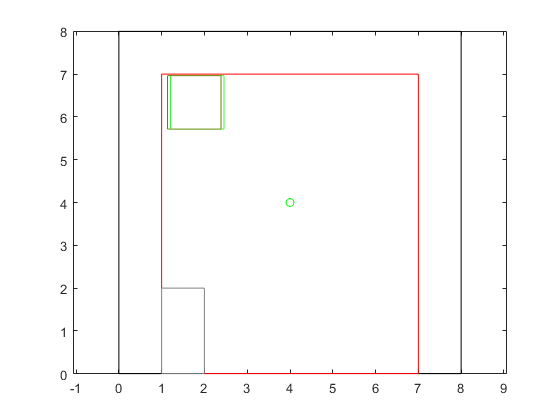

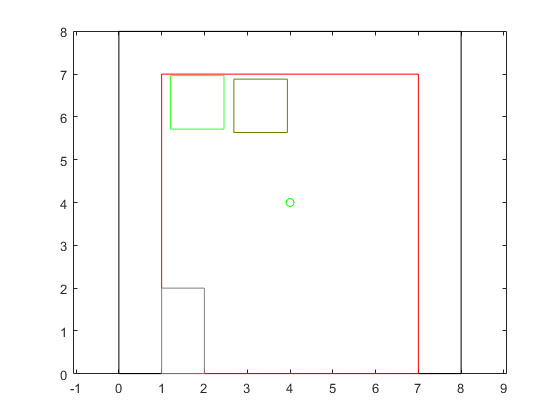

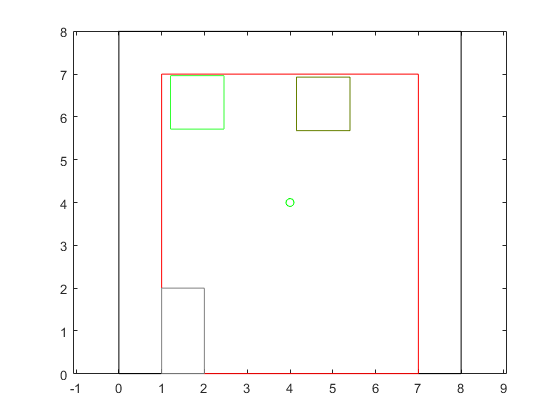

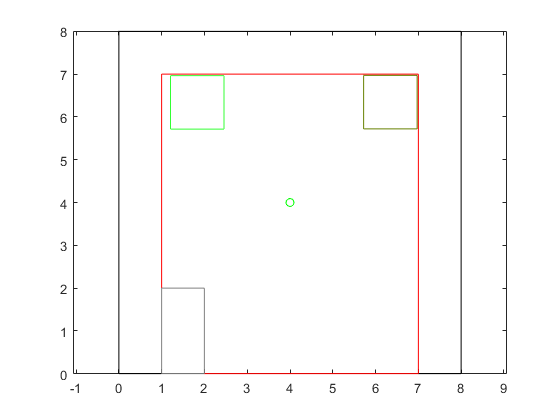

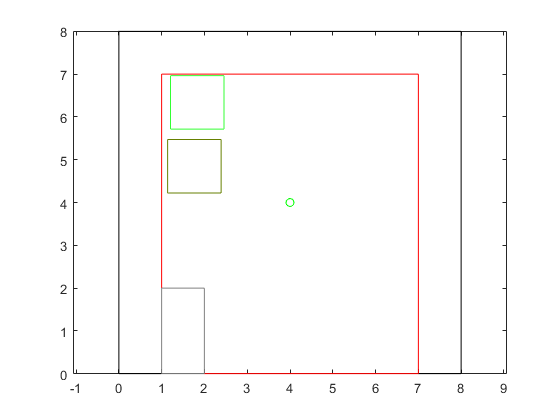

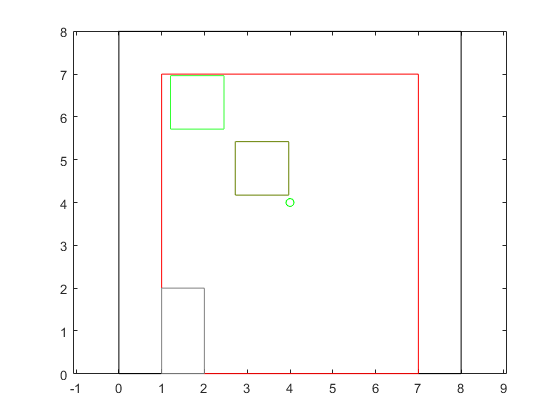

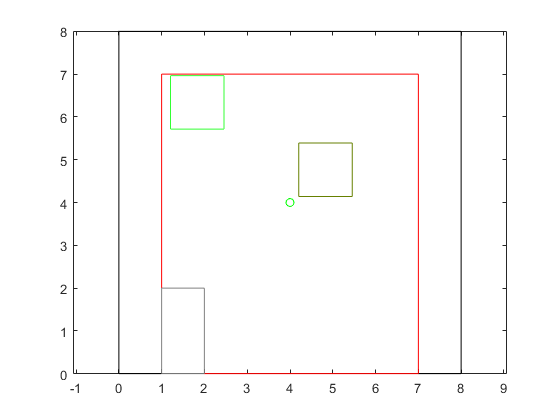

%Dimensions of the House
xStart = 0;
yStart = 0;
height = 8;
width = 8;
doorX = 1;
doorY = 2;
windW = 1.25;
windH = 1.25;
margin = 1;
windMargin = 0.125;
doorStep = 1;
data = 0;

%Find all possible configurations
for door = margin:doorStep:(width-margin-doorX)
    name = num2str(door);
    hold on
    %%%Margin
    grey = [0.5 0.5 0.5]; %color
    
    
    for wind1 = 0:1 %possible Locations THIS IS BAD CODE ESPECIALLY WITH MOD
        colW1 = mod(wind1,4); %Value from 0 to 2
        rowW1 = floor(wind1/4); %Value from 0 to 2
        windX = margin + colW1*(2* windMargin + windW) + windMargin + 0.1 * rand();
        windY = height - margin - (rowW1+1)*(2*windMargin + windW) + windMargin + 0.1 * rand();
        

        for wind2 = wind1+1:11
            colW2 = mod(wind2,4);
            rowW2 = floor(wind2/4);
            windX2 = margin + colW2*(2* windMargin + windW) + windMargin + 0.1 * rand();
            windY2 = height - margin - (rowW2+1)*(2*windMargin + windW) + windMargin + 0.1 * rand();
            
            figure('Name',name);
            plotSquare(xStart, yStart, width, height,[0 0 0]);
            hold on
            plotSquare(1,0,6,7,'r');
            plotSquare(door,yStart, doorX, doorY, grey);
            plotSquare(windX, windY, windW, windH, [0.2 1 0.2]);
            plotSquare(windX2, windY2, windW, windH, [0.4 0.5 0]);  
            plot(4,4,'go')
            
            axis equal;
            data = data + 1;
        end
    end
end

data

data = 138